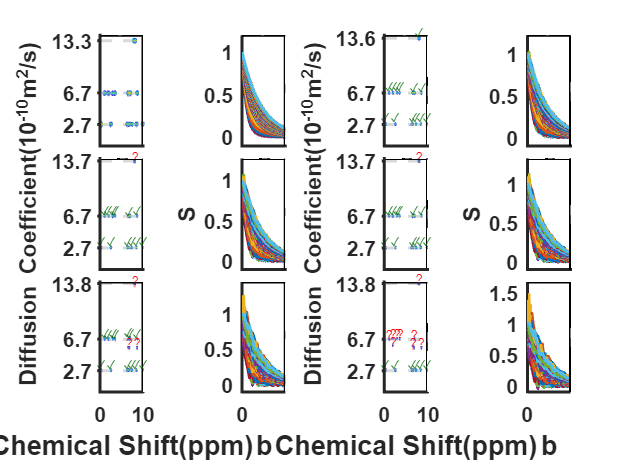

close all;clear;clc

data = load('Data/eval/eval.mat');

test_out = data.test_out;
test_input = data.test_input;
max_var = data.max_var;
merged_boxes = data.merged_boxes;

x = linspace(0, 10, 300);
y = linspace(0, 14, 140);
b = linspace(0, 0.8, 30);
[X, Y] = meshgrid(x, y);
SNR = [135, 100, 75, 55, 40];

figure;
tiledlayout(3, 4, 'Padding', 'loose', 'TileSpacing', 'tight');

for i = 2:6
    dB = 36 - 3*i;
    % noise = test_input(i,:,:)-test_input(1,:,:);
    % HNMR = squeeze(sum(data.cif,2)/max(sum(data.cif,2)));
    % sinal = HNMR.*squeeze(test_input(i,:,1));
    % SNR = round(max(sinal(:))/(2*std(reshape(HNMR.*noise, 1, []))));
    nexttile(i*2-1);
    test_input(i, :, :) = test_input(i, :, :) ./ test_input(i,:, 1);
    low = 0;
    total = 0;
    contour(X, Y, squeeze(test_out(i,:,:))' , 40);

    if i == 4 || i == 3
        ylabel('Diffusion Coefficient(10^{-10}m^2/s)', 'FontSize', 18);
    end

    box off;
    set(gca, 'LineWidth', 2, 'TickDir','out','FontSize',14,'FontWeight','bold');
    xLimits = xlim;
    yLimits = ylim;
    line([xLimits(1), xLimits(2)], [yLimits(2), yLimits(2)], 'Color', 'k', 'LineWidth', 2);
    line([xLimits(2), xLimits(2)], [yLimits(1), yLimits(2)], 'Color', 'k', 'LineWidth', 2);


    hold on;
    boxes = merged_boxes.(['dB', num2str(dB)]);
    diff_values = max_var.(['dB', num2str(dB)]);
    
    for j = 1:length(boxes)
        if diff_values(j) == 0
            continue;
        end
        bb = boxes(j, :, :);
        x1 = x(bb(1,1,1)+1);
        x2 = x(bb(1,2,1)+1);
        y1 = y(bb(1,1,2)+1);
        y2 = y(bb(1,2,2)+1);
        width = x2 - x1;
        height = y2 - y1;
        total = total + 1;

        if diff_values(j) <= 0.5
            color = [0 0.4 0]; % RGB for green 
            symbols = '✓';
            fontsize = 8;
            low = low + 1;
        else
            color = 'r'; % Red 
            symbols = '?';
            fontsize = 8;
        end
        centreX = (x2 + x1) / 2;
        x_rect = [x1, x2, x2, x1];
        y_rect = [y1, y1, y2, y2];
        h_rect = fill(x_rect, y_rect, color,'EdgeColor', 'none', 'FaceAlpha', 0.3); 

        DiffCoef = [2.7, 6.7, 13.6; 2.7, 6.7, 13.7;2.7, 6.7, 13.7;2.7, 6.7, 13.8;2.7, 6.7, 13.8];
        Diff = squeeze(DiffCoef(i-1,:));
        for k = 1:length(Diff)
            l = line(gca,get(gca,'xlim'),Diff(k)*ones(1,2),'LineWidth',2,'color',[0.85 0.85 0.85],'LineStyle','--');
            uistack(l, "bottom");
        end
        set(gca,'YTick',unique(Diff));
        uistack(h_rect, 'bottom');
        text(centreX, y1 + 0.07 * 14, symbols, 'Color', color, 'FontSize', fontsize, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle');

        % rectangle('Position', [x1, y1, width, height], 'EdgeColor', color, 'FaceColor', color, 'LineWidth', 1, 'FaceAlpha', 0.5);
    end

    CR_ratio = low/total;
    
    if i ~= 5 && i ~= 6
        set(gca, 'XTickLabel', {},'xtick',[],'LineWidth', 2,'FontSize',14,'FontWeight','bold');
    else 
        xlabel('Chemical Shift(ppm)', 'FontSize', 18);
    end
    nexttile(i*2);
    S = squeeze(test_input(i, :, :));
    plot(b, S','LineWidth', 2);

    if i == 4 || i == 3
        ylabel('S', 'FontSize', 18);
    end
    
    box off;
    set(gca, 'LineWidth', 2, 'TickDir','out','FontSize',14,'FontWeight','bold');
    xlim([0, 0.8]); 

    ylim([-0.1, max(S(:))+0.2]);
    xLimits = xlim;
    yLimits = ylim;
    line([xLimits(1), xLimits(2)], [yLimits(2), yLimits(2)], 'Color', 'k', 'LineWidth', 2);
    line([xLimits(2), xLimits(2)], [yLimits(1), yLimits(2)], 'Color', 'k', 'LineWidth', 2);

    if i ~= 5 && i ~= 6
        set(gca, 'XTickLabel', {},'xtick',[],'LineWidth', 2,'FontSize',14,'FontWeight','bold');
    else 
        xlabel('b', 'FontSize', 18);
    end
    hold off;
end

% Ideal Signal
ax = nexttile(2);
S = squeeze(test_input(1, :, :));
plot(b, S', 'LineWidth', 2);
xlim([0, 0.8]); 
ylim([-0.1, max(S(:))+0.2]);
box off;
xLimits = xlim;
yLimits = ylim;
line([xLimits(1), xLimits(2)], [yLimits(2), yLimits(2)], 'Color', 'k', 'LineWidth', 2);
line([xLimits(2), xLimits(2)], [yLimits(1), yLimits(2)], 'Color', 'k', 'LineWidth', 2);

set(gca, 'TickDir','out', 'LineWidth', 2,'xtick',[],'FontSize',14,'FontWeight','bold');

% Ground Truth
nexttile(1);
contour(X, Y, squeeze(test_out(1, :, :))', 40, 'LineWidth', 2); % Thicker contour lines
box off;
xLimits = xlim;
yLimits = ylim;
line([xLimits(1), xLimits(2)], [yLimits(2), yLimits(2)], 'Color', 'k', 'LineWidth', 2);
line([xLimits(2), xLimits(2)], [yLimits(1), yLimits(2)], 'Color', 'k', 'LineWidth', 2);

DiffCoef = [2.7, 6.7, 13.3];
for k = 1:length(DiffCoef)
    l = line(gca,get(gca,'xlim'),DiffCoef(k)*ones(1,2),'LineWidth',2,'color',[0.85 0.85 0.85],'LineStyle','--');
    uistack(l, "bottom");
end
set(gca,'YTick',unique(DiffCoef));
set(gca, 'XTickLabel', {},'xtick',[],'LineWidth', 2, 'TickDir','out','FontSize',14,'FontWeight','bold');

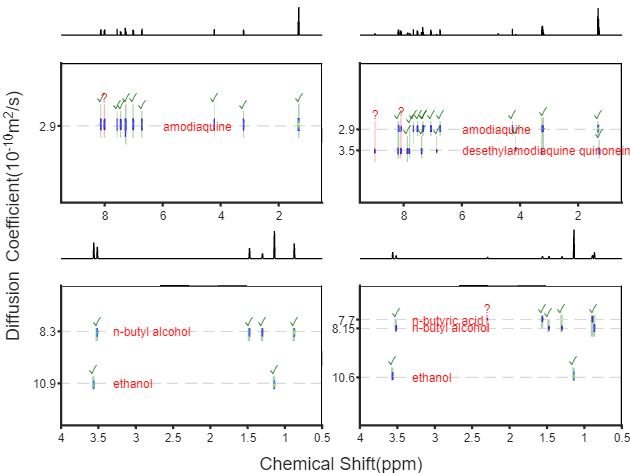

close all;clear;clc


figure;
t = tiledlayout(8, 2, 'Padding', 'tight', 'TileSpacing', 'tight');

load AMO_net_input;
load AMO_Result.mat;

nexttile
Type = "AMO";
cs1 = 0.5;
cs2 = 9.5;
dc1 = 2;
dc2 = 4;

contourDOSY_SPL(Type, 0, Z, HNMR, b, ppm, 0, idx_peaks, cs1, cs2, dc1, dc2, t, max_var, box);
load AD_Result.mat;
load AD_net_input;


nexttile
Type = "AD";
cs1 = 0.5;
cs2 = 9.5;
dc1 = 1;
dc2 = 5;

contourDOSY_SPL(Type, 0, Z, HNMR, b, ppm, 0, idx_peaks, cs1, cs2, dc1, dc2, t, max_var, box);
load BPP1_net_input;
load BPP1_Result.mat;

nexttile

Type = "BPP1";

cs1 = 0.5;
cs2 = 4;
dc1 = 6;              
dc2 = 13;

contourDOSY_SPL(Type, 0, Z, HNMR, b, ppm, 0, idx_peaks, cs1, cs2, dc1, dc2, t, max_var, box);
load BPP2_net_input;
load BPP2_Result.mat;

nexttile

Type = "BPP2";

cs1 = 0.5;
cs2 = 4;
dc1 = 6;              
dc2 = 13;

contourDOSY_SPL(Type, 0, Z, HNMR, b, ppm, 0, idx_peaks, cs1, cs2, dc1, dc2, t, max_var, box);

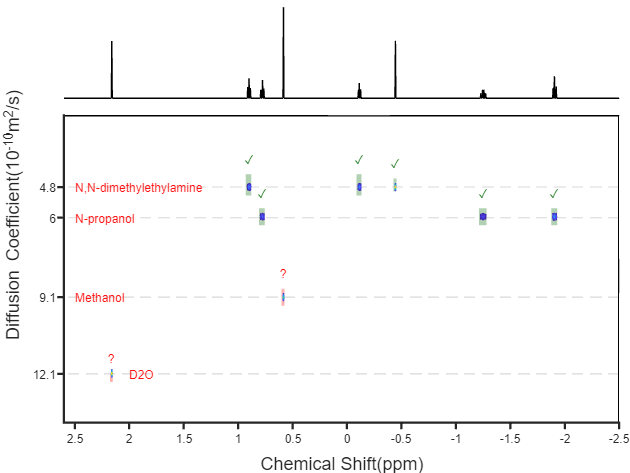

close all;clear;clc
load MPD_net_input;
load MPD_Result.mat;

figure;
t = tiledlayout(4,1);
t.TileSpacing = 'tight';
t.Padding = 'tight';
nexttile
Type = "MPD";
cs1 = -2.5;
cs2 = 2.6;
dc1 = 2;
dc2 = 14;

contourDOSY_SPL(Type, 0, Z, HNMR, b, ppm, 0, idx_peaks, cs1, cs2, dc1, dc2, t, max_var, box);   

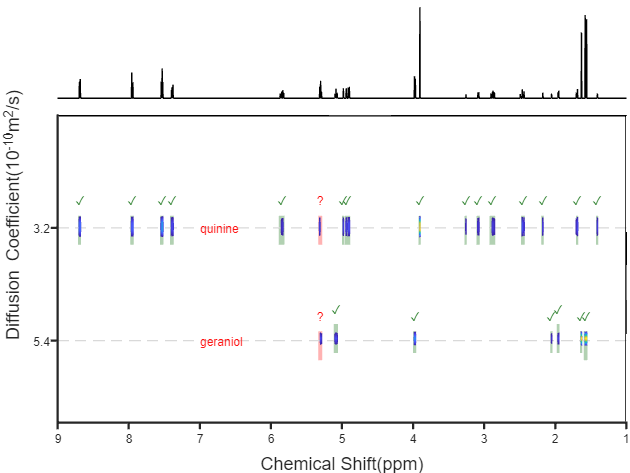

close all;clear;clc
load QG_net_input;
load QG_Result.mat;
load QG_Result_DRILT.mat;

figure;
t = tiledlayout(4,1);
t.TileSpacing = 'tight';
t.Padding = 'tight';
nexttile
Type = "QG";
cs1 = 1;
cs2 = 9;
dc1 = 1;
dc2 = 7;

contourDOSY_SPL(Type, QG_Result_DRILT, Z, HNMR, b, ppm, idx_peaks_DRILT, idx_peaks, cs1, cs2, dc1, dc2, t, max_var, box);   

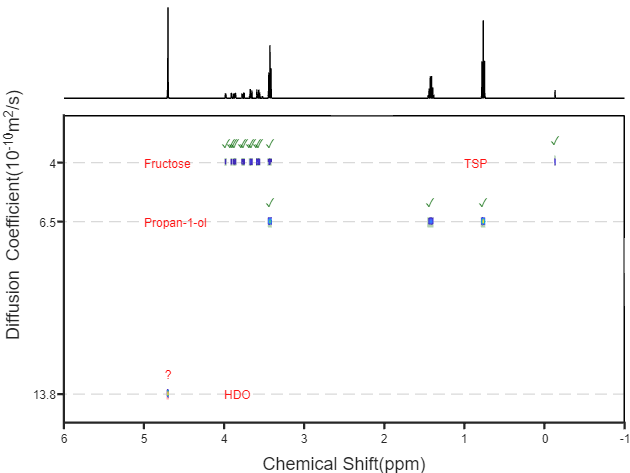

close all;clear;clc
load FPH_net_input;
load FPH_Result.mat;

figure;
t = tiledlayout(4,1);
t.TileSpacing = 'tight';
t.Padding = 'tight';
nexttile
Type = "FPH";
cs1 = -1;
cs2 = 6;
dc1 = 2;
dc2 = 15;

contourDOSY_SPL(Type, 0, Z, HNMR, b, ppm, 0, idx_peaks, cs1, cs2, dc1, dc2, t, max_var, box);

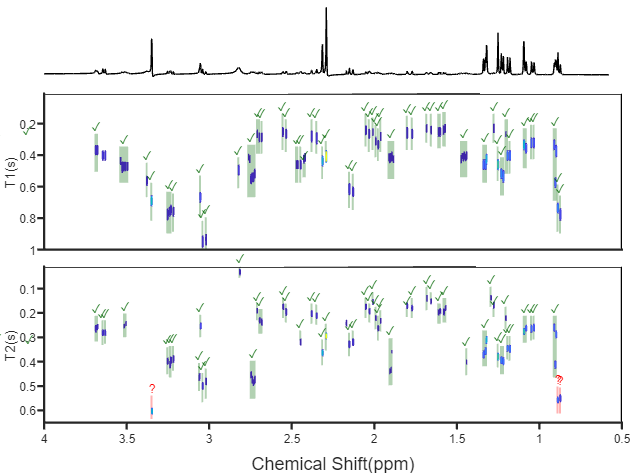

close all;clear;clc
load T1Data.mat
load T1_net_input.mat
load T1_Result.mat;

figure;
t = tiledlayout(5,1);
t.TileSpacing = 'tight';
t.Padding = 'tight';
nexttile
cs1 = 0.5;
cs2 = 4;
dc1 = 0.01;
dc2 = 1;


T1Data = NmrData.SPECTRA;
if size(T1Data,1)>size(T1Data,2)
    T1Data = T1Data.';  
end  
cs=NmrData.Specscale;     % chemical shift
ppm = cs;

T1Data = real(T1Data);
T1Data = -T1Data / max(T1Data(:));

cs_spec = T1Data(1, :);
plot(ppm,cs_spec, Color='k');set(gca,'Xdir','reverse');set(gca,'Ydir','reverse');axis off;
xlim([cs1,cs2]);
spec_whole = zeros([length(Z(1, :)), length(ppm)]);
spec_whole(:, idx_peaks) = Z.';

nexttile(2, [2, 1])

decay_range = linspace(0, 1, length(Z(1, :)));
contour(ppm, decay_range*32/20, spec_whole, 100);
xlim([cs1,cs2]);
ylim([dc1,dc2]);
box off;
xLimits = xlim;
yLimits = ylim;
line([xLimits(1), xLimits(2)], [yLimits(1), yLimits(1)], 'Color', 'k', 'LineWidth', 1.5);
line([xLimits(1), xLimits(1)], [yLimits(1), yLimits(2)], 'Color', 'k', 'LineWidth', 1.5);
set(gca,'Ydir','reverse','Xdir','reverse','TickDir','out', 'LineWidth', 1.5); 
set(gca,'xtick',[])
ylabel('T1(s)');

hold on; 
low = 0;
total = 0;
yIndices = 1:length(decay_range);
decay_range = double(decay_range);
for idx = 1:length(box)
    bb = box(idx, :, :);
    diff = max_var(idx);
    if diff == 0
        continue;
    end
    total = total + 1;
    x1 = bb(1, 1, 1)+1;
    x2 = bb(1, 2, 1)+1;
    y1 = bb(1, 1, 2)+1;
    y2 = bb(1, 2, 2)+1;
    try
        x1Mapped = ppm(1, x1);
        x2Mapped = ppm(1, x2);
        y1Mapped = interp1(double(yIndices), decay_range*32/20, double(y1), 'linear', 'extrap');
        y2Mapped = interp1(double(yIndices), decay_range*32/20, double(y2), 'linear', 'extrap');
    catch e
        fprintf('Error during interpolation: %s\n', e.message);
        continue;
    end

    centreX = (x2Mapped + x1Mapped) / 2;
    horizD = dc2 - dc1; 
    horizC = cs2 - cs1;
    if diff <= 0.5
        color = [0 0.4 0]; % RGB for green 
        symbols = '✓';
        fontsize = 8;
        low = low + 1;
    else
        color = 'r'; % Red 
        symbols = '?';
        fontsize = 8;
    end

    x_rect = [x1Mapped-0.001*horizC, x2Mapped+0.001*horizC, x2Mapped+0.001*horizC, x1Mapped-0.001*horizC];
    y_rect = [y1Mapped, y1Mapped, y2Mapped, y2Mapped];
    h_rect = fill(x_rect, y_rect, color,'EdgeColor', 'none', 'FaceAlpha', 0.3); 

    uistack(h_rect, 'bottom');
    text(centreX, y1Mapped - 0.05 * horizD, symbols, 'Color', color, 'FontSize', fontsize, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle');

end

hold off;


load T2Data.mat
load T2_net_input.mat
load T2_Result.mat;


nexttile
cs1 = 0.5;
cs2 = 4;
dc1 = 0.01;
dc2 = 0.65;


T1Data = NmrData.SPECTRA;
if size(T1Data,1)>size(T1Data,2)
    T1Data = T1Data.';  
end  
cs=NmrData.Specscale;     % chemical shift
ppm = cs;

T1Data = real(T1Data);
T1Data = -T1Data / max(T1Data(:));

cs_spec = T1Data(1, :);
plot(ppm,cs_spec, Color='k');set(gca,'Xdir','reverse');set(gca,'Ydir','reverse');axis off;
xlim([cs1,cs2]);
spec_whole = zeros([length(Z(1, :)), length(ppm)]);
spec_whole(:, idx_peaks) = Z.';

nexttile(4, [2, 1])

decay_range = linspace(0, 1, length(Z(1, :)));
contour(ppm, decay_range*12.8/20, spec_whole, 100);
xlim([cs1,cs2]);
ylim([dc1,dc2]);
box off;
xLimits = xlim;
yLimits = ylim;
line([xLimits(1), xLimits(2)], [yLimits(1), yLimits(1)], 'Color', 'k', 'LineWidth', 1.5);
line([xLimits(1), xLimits(1)], [yLimits(1), yLimits(2)], 'Color', 'k', 'LineWidth', 1.5);
set(gca,'Ydir','reverse','Xdir','reverse','TickDir','out', 'LineWidth', 1.5); 
ylabel('T2(s)');
xlabel(t, 'Chemical Shift(ppm)');
hold on; 
low = 0;
total = 0;
yIndices = 1:length(decay_range);
decay_range = double(decay_range);
for idx = 1:length(box)
    bb = box(idx, :, :);
    diff = max_var(idx);
    if diff == 0
        continue;
    end
    total = total + 1;
    x1 = bb(1, 1, 1)+1;
    x2 = bb(1, 2, 1)+1;
    y1 = bb(1, 1, 2)+1;
    y2 = bb(1, 2, 2)+1;
    try
        x1Mapped = ppm(1, x1);
        x2Mapped = ppm(1, x2);
        y1Mapped = interp1(double(yIndices), decay_range*12.8/20, double(y1), 'linear', 'extrap');
        y2Mapped = interp1(double(yIndices), decay_range*12.8/20, double(y2), 'linear', 'extrap');
    catch e
        fprintf('Error during interpolation: %s\n', e.message);
        continue;
    end

    centreX = (x2Mapped + x1Mapped) / 2;
    horizD = dc2 - dc1; 
    horizC = cs2 - cs1;
    if diff <= 0.5
        color = [0 0.4 0]; % RGB for green 
        symbols = '✓';
        fontsize = 8;
        low = low + 1;
    else
        color = 'r'; % Red 
        symbols = '?';
        fontsize = 8;
    end

    x_rect = [x1Mapped-0.001*horizC, x2Mapped+0.001*horizC, x2Mapped+0.001*horizC, x1Mapped-0.001*horizC];
    y_rect = [y1Mapped, y1Mapped, y2Mapped, y2Mapped];
    h_rect = fill(x_rect, y_rect, color,'EdgeColor', 'none', 'FaceAlpha', 0.3); 
    
    uistack(h_rect, 'bottom');
    text(centreX, y1Mapped - 0.05 * horizD, symbols, 'Color', color, 'FontSize', fontsize, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle');

end

hold off;